# An Analysis on the Stability of an Integral Compensator Feedback Circuit

In this program we will be building a state space model of the circuitry that commonly controls motors.  We will first be looking to the a second order stable system, and then a third order unstable system, in order to compare the fundamental differences between the two.

## Second Order System:

In our second order system, the entire circuit can be modeled through a set of two differential equations which describe the voltage output of an "integral compensator" circuit, and the current rotational velocity of the wheel.  These equations are written in terms of the positive real constants Ks, Km, J, and Req.  All of these elements were measured during the construction of the circuit.  There is one input element to the system, Vref.  The equations governing the system are shown below:

- 
$$\frac{dVo}{dt} = \frac{1}{R_I C_I}(V_{Ref} - K_s \omega)$$


- 
$$\frac{d\omega}{dt} = \frac{K_m}{JR_{eq}} (V_o - K_m \omega  )$$


We can combine these two equations into one state space vector system.  We first define a column vector x = [Vo w].  Then we build the following matrix  system   


$$\frac{d{\underline{x}}}{dt} = A\underline{x} + \underline{b} u$$



$$\left\lbrack \begin{array}{c}
\frac{{dV}_O }{dt}\\
\frac{d\omega }{dt}
\end{array}\right\rbrack =\text{ }\left\lbrack \begin{array}{c}
0 & \frac{−K_s }{R_I C_I }\\
\frac{K_m }{{JR}_{eq} } & \frac{K_m^2 }{{JR}_{eq} }
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
V_O \\
\omega 
\end{array}\right\rbrack +\text{ }\left\lbrack \begin{array}{c}
\frac{1}{R_I C_I }\\
0
\end{array}\right\rbrack V_{ref}$$


This system translated into symobolic matlab is shown below

syms Ks RI CI Km J Req Vref
S2 = [0, -Ks/(RI*CI); (Km/(J*Req)), -Km*(Km/(J*Req))]

$$S2 = \left(\begin{array}{cc} 0 & -\frac{\mathrm{Ks}}{\mathrm{CI}\,\mathrm{RI}}\\ \frac{\mathrm{Km}}{J\,\mathrm{Req}} & -\frac{{\mathrm{Km}}^{2}}{J\,\mathrm{Req}} \end{array}\right)$$

b2 = Vref*[1/(RI*CI); 0]

$$b2 = \left(\begin{array}{c} \frac{\mathrm{Vref}}{\mathrm{CI}\,\mathrm{RI}}\\ 0 \end{array}\right)$$

In order to verify this system, we can look to its steady state solution.  The system wherein $\frac{dx}{dt}=\underline{0}$ meaning we will never leave it for all time t.  In our physical system we know that $0\le V_{Ref} \le 5$.  We also know that $0\le V_O \le 10$ so we expect to see steady state solutions where our reference input almost fully maps our output.  We find these solutions by solving the equation  $ A\underline{x}  = - \underline{b} u$.  Below we wave calculated the solutions for two separate reference voltages.

%Take the Symbolic matrix and substitte in the Actual values
A2 = subs(S2,Ks,.4321);                       %Ksense is the transfer function between w and voltage in the circuit
A2 = subs(A2,RI,42e3);                        %RI is a 42k resistor in the integral compensator
A2 = subs(A2,CI,1e-6);                        %CI is a 1uF capacitor in the intragral compensator
A2 = subs(A2,Km,.858);                        %This value is the transfer function between w and volts
A2 = subs(A2,J,2e-3);                         %A measure of the inertia stored in the spinning wheel
Rm = 2.6775;                                  %The resistance inside the motor
Rb = 517;                                     %The gate resistances of the motor driver circuit
Beta = 200;                                   %Current gain through a transistor
A2 = double(subs(A2,Req,Rm + 2*Rb/(1+Beta)))  %The combined resistance that actually impacts the circuit

A2 =          0  -10.2881
   54.8469  -47.0586


%Similarly stubstitute for the b vector
Ab2 = subs(b2,RI,42e3);
Ab2 = subs(Ab2,CI,1e-6) %The general steady state solution

$$Ab2 = \left(\begin{array}{c} \frac{500\,\mathrm{Vref}}{21}\\ 0 \end{array}\right)$$

%Now that we have the A matrix and b vector, subtract the b vector and evaluate the left division for each system
SS1 = double(A2 \ -(subs(Ab2,Vref,1)))

SS1 =     1.9857
    2.3143


SS5 = double(A2 \ -(subs(Ab2,Vref,5)))

SS5 =     9.9283
   11.5714


These steady state solutions show that there are desireable solutions to our differential equations, but we need to determine the stability of our system in order to know whether our system will approach these solutions as time progresses, and if they do, we want to be able to qualify the speed with which they converge.

An analysis of stability is done by calculating the eigen values of the state space matrix A, and looking at the sign of the real portion of the complex roots.

Seig2 = simplify(eig(S2))

$$Seig2 = \left(\begin{array}{c} -\frac{\sqrt{-\frac{\mathrm{Km}\,\left(4\,J\,\mathrm{Ks}\,\mathrm{Req}-\mathrm{CI}\,{\mathrm{Km}}^{3}\,\mathrm{RI}\right)}{\mathrm{CI}\,\mathrm{RI}}}+{\mathrm{Km}}^{2}}{2\,J\,\mathrm{Req}}\\ \frac{\sqrt{-\frac{\mathrm{Km}\,\left(4\,J\,\mathrm{Ks}\,\mathrm{Req}-\mathrm{CI}\,{\mathrm{Km}}^{3}\,\mathrm{RI}\right)}{\mathrm{CI}\,\mathrm{RI}}}-{\mathrm{Km}}^{2}}{2\,J\,\mathrm{Req}} \end{array}\right)$$

A solution is said to be asymptotically stable if and only if the real part of all eigenvalues is less than zero.  In the above system the first value is the negation of two numbers that must be positive, so it must always be zero.  In the second value the positive portion is not only under a square root, but contains a capacitance which generally will be orders of magnitudes smaller than all of the other terms in the equation.  So the system will almost always be stable.  This analysis is verified in looking to our specific system:

Aeig2 = eig(A2)

Aeig2 =  -23.5293 + 3.2621i
 -23.5293 - 3.2621i


Both of the eigen values shown above have negative real parts, we can easily visualize this system by plotting the eigen values on the complex plane

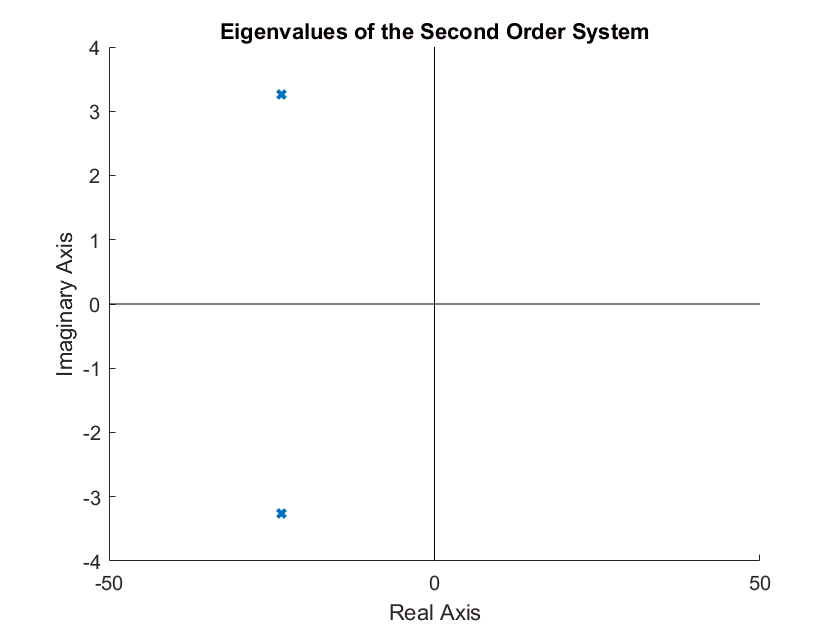

scatter(real(Aeig2),imag(Aeig2),'x','Linewidth',2)  %Plot the poles of the system
title('Eigenvalues of the Second Order System')
xlabel('Real Axis')
ylabel('Imaginary Axis')
line ([0 0], [-4 4],'Color',[0 0 0])
line( [-50 50], [0 0],'Color',[0 0 0])

We have now solved for the steady state solutions to our system, and shown that they are stable solutions.  However we still have no information on how long it takes for our system to arrive at this steady state solution.  We can accomplish this by calculating the generic solution to this system as a function of time through the following process

%This is the code for the classic simple harmonic oscilator system which we used to make sure we were following the corect process
%In this stage.  With initial conditions of zero, and frequency of one the oscilator should never move, with an output of [1 ; 0]
% syms t
% A = [0 1; -1 0];
% Aoft = simplify(expm(A*t)); % Create the exponent function of A: e^(A(t-t0)
% syms j
% intA = simplify(expm(A*(t-j))); %Create the exponent fucntion of A: e^(A(t-j)) 
% % Take the Multiply the exponent function by the initial conditions and add the integral of the integral portion to create the 
% % function x(t)
% Xoft = Aoft*[1;0] + int(intA * [0;1],j,0,t)

%Now that we've verified that this process works as expected, we can apply it to our system
%Our intial conditions are [0 0]' at T0 = 0  The other portions of the equation were defined above.
syms t
%Create the exponent function of A e^At for all time t
A2oft = simplify(expm(A2.*t))

$$A2oft = \begin{array}{l} \left(\begin{array}{cc} \frac{\sigma_{3}}{2}+\frac{\sigma_{4}}{2}-\sigma_{1}+\sigma_{2} & \frac{38007917948960768\,\sqrt{580959484024064640498995874603735}\,\sigma_{3}\,\mathrm{i}}{580959484024064640498995874603735}-\frac{38007917948960768\,\sqrt{580959484024064640498995874603735}\,\sigma_{4}\,\mathrm{i}}{580959484024064640498995874603735}\\ -\frac{3859504694410007\,\sqrt{580959484024064640498995874603735}\,\sigma_{3}\,\mathrm{i}}{11065894933791707438076111897214}+\frac{3859504694410007\,\sqrt{580959484024064640498995874603735}\,\sigma_{4}\,\mathrm{i}}{11065894933791707438076111897214} & \frac{\sigma_{3}}{2}+\frac{\sigma_{4}}{2}+\sigma_{1}-\sigma_{2} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\frac{1655727513901893\,\sqrt{580959484024064640498995874603735}\,\sigma_{3}\,\mathrm{i}}{11065894933791707438076111897214}\\ \sigma_{2}=\frac{1655727513901893\,\sqrt{580959484024064640498995874603735}\,\sigma_{4}\,\mathrm{i}}{11065894933791707438076111897214}\\ \sigma_{3}={\mathrm{e}}^{\frac{t\,\left(-173851388959698765+\sqrt{580959484024064640498995874603735}\,\mathrm{i}\right)}{7388718138654720}}\\ \sigma_{4}={\mathrm{e}}^{-\frac{t\,\left(173851388959698765+\sqrt{580959484024064640498995874603735}\,\mathrm{i}\right)}{7388718138654720}} \end{array}$$

syms j
%Create the function e^A(t-j) for the dummy variable j overwhich we will integrate to t.
intA2oft = simplify(expm(A2.*(t-j)));
%Now add the exponent function and integrate over the integral portion to find the full solution to the diffeq
done = A2oft*[0;0] + int(intA2oft * Ab2,j,0,t)

$$done = \begin{array}{l} \left(\begin{array}{c} \frac{33114550278037860000\,\mathrm{Vref}}{16676919784545640247}-\frac{16557275139018930000\,\mathrm{Vref}\,\sigma_{2}}{16676919784545640247}-\frac{16557275139018930000\,\mathrm{Vref}\,\sigma_{3}}{16676919784545640247}-\frac{282317580563737190426612987313538000\,\sqrt{580959484024064640498995874603735}\,\mathrm{Vref}\,\sigma_{2}\,\mathrm{i}}{1937722942628070082318487023539849938812800598504509}+\frac{282317580563737190426612987313538000\,\sqrt{580959484024064640498995874603735}\,\mathrm{Vref}\,\sigma_{3}\,\mathrm{i}}{1937722942628070082318487023539849938812800598504509}\\ \frac{1000\,\sqrt{580959484024064640498995874603735}\,\mathrm{Vref}\,\left({\mathrm{e}}^{-\frac{t\,\sigma_{1}}{7388718138654720}}-1\right)\,\left(-173851388959698765+\sqrt{580959484024064640498995874603735}\,\mathrm{i}\right)\,\mathrm{i}}{502065186093596662319232234832547787}+\frac{1000\,\sqrt{580959484024064640498995874603735}\,\mathrm{Vref}\,{\mathrm{e}}^{-\frac{1655727513901893\,t}{70368744177664}}\,\left({\mathrm{e}}^{\sigma_{4}}-{\mathrm{e}}^{\frac{1655727513901893\,t}{70368744177664}}\right)\,\sigma_{1}\,\mathrm{i}}{502065186093596662319232234832547787} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=173851388959698765+\sqrt{580959484024064640498995874603735}\,\mathrm{i}\\ \sigma_{2}={\mathrm{e}}^{-\frac{1655727513901893\,t}{70368744177664}-\sigma_{4}}\\ \sigma_{3}={\mathrm{e}}^{-\frac{1655727513901893\,t}{70368744177664}+\sigma_{4}}\\ \sigma_{4}=\frac{\sqrt{580959484024064640498995874603735}\,t\,\mathrm{i}}{7388718138654720} \end{array}$$


%We still need to apply our input to this system in order to evaluate it.  Evaluating with respect to Vref = 5 
%Creates the following function of time
fiveIn = subs(done,Vref,5)

$$fiveIn = \begin{array}{l} \left(\begin{array}{c} \frac{165572751390189300000}{16676919784545640247}-\frac{82786375695094650000\,\sigma_{3}}{16676919784545640247}+\frac{1411587902818685952133064936567690000\,\sqrt{580959484024064640498995874603735}\,\sigma_{3}\,\mathrm{i}}{1937722942628070082318487023539849938812800598504509}-\frac{82786375695094650000\,\sigma_{2}}{16676919784545640247}-\frac{1411587902818685952133064936567690000\,\sqrt{580959484024064640498995874603735}\,\sigma_{2}\,\mathrm{i}}{1937722942628070082318487023539849938812800598504509}\\ \frac{5000\,\sqrt{580959484024064640498995874603735}\,\left({\mathrm{e}}^{-\frac{t\,\sigma_{1}}{7388718138654720}}-1\right)\,\left(-173851388959698765+\sqrt{580959484024064640498995874603735}\,\mathrm{i}\right)\,\mathrm{i}}{502065186093596662319232234832547787}+\frac{5000\,\sqrt{580959484024064640498995874603735}\,{\mathrm{e}}^{-\frac{1655727513901893\,t}{70368744177664}}\,\left({\mathrm{e}}^{\sigma_{4}}-{\mathrm{e}}^{\frac{1655727513901893\,t}{70368744177664}}\right)\,\sigma_{1}\,\mathrm{i}}{502065186093596662319232234832547787} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=173851388959698765+\sqrt{580959484024064640498995874603735}\,\mathrm{i}\\ \sigma_{2}={\mathrm{e}}^{-\frac{1655727513901893\,t}{70368744177664}-\sigma_{4}}\\ \sigma_{3}={\mathrm{e}}^{-\frac{1655727513901893\,t}{70368744177664}+\sigma_{4}}\\ \sigma_{4}=\frac{\sqrt{580959484024064640498995874603735}\,t\,\mathrm{i}}{7388718138654720} \end{array}$$


%Evaluating this solution for an arbitrary long amount of time provides the following solution.  Which is the same
%Steady state solution we calculated before through our state space analysis. Verifying our model
SS5Calculated = round(double(subs(fiveIn,t,1)),4)

SS5Calculated =     9.9283
   11.5714


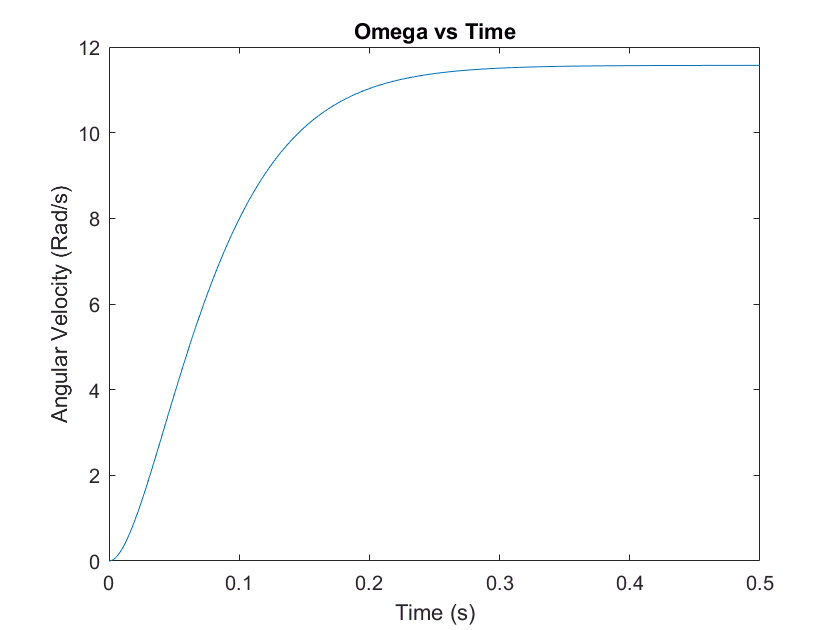


%Here is a plot of w over time as it rises to the steady state
time = linspace(0,.5,1000);
xout = round(double(subs(fiveIn,t,time)),4);
plot(time,xout(2,:))
title('Omega vs Time')
xlabel('Time (s)')
ylabel('Angular Velocity (Rad/s)')

## Third Order System:

As we saw earlier it is really hard to create an unstable second order system.  For that reason we decided to add another component in order to achieve instability.This capacitor acts as a low-pass filter, transforming the output of the wheel's encoder before it has a chance to reach the integral compensator.  We call this new value Vs, and it comes with two new defining terms, Rx and Cx. The resistance and capacitance used in the filter.  The new state system is shown below:


$$\left\lbrack \begin{array}{c}
\frac{{\text{dV}}_O }{\text{dt}}\\
\frac{d\omega }{\text{dt}}\\
\frac{{\text{dV}}_s }{\text{dt}}
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
0 & 0 & −\frac{1}{R_I C_I }\\
\frac{K_m }{{\text{JR}}_{\text{eq}} } & \frac{K_m^2 }{{\text{JR}}_{\text{eq}} } & 0\\
0 & \frac{K_s }{\left(C_{x\text{ }} R_x \right)} & \left(−\frac{1}{R_I }−\frac{1}{R_x }\right)\frac{1}{C_x }
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
V_O \\
\omega \\
V_s 
\end{array}\right\rbrack +\text{ }\left\lbrack \begin{array}{c}
\frac{1}{R_I C_I }\\
0\\
\frac{1}{C_x R_I }
\end{array}\right\rbrack V_{\text{Ref}}$$


This system is entered into Matlab symbolically below.

syms Rx Cx
S3 = [0 0 -1/(RI*CI); Km/(J*Req) Km^2/(J*Req) 0; 0 Ks/(Cx*Rx) (-1/RI - 1/Rx)/Cx];
b3 = [1/(RI*CI);0; 1/(Cx*RI)];

Now to analyze our final system we need to begin supplying values into the system

%First take the symbolic matrix and stubstitute in the calculated values
A3 = subs(S3,Ks,.4321);                        %Ksense is the transfer function between w and voltage in the circuit
A3 = subs(A3,RI,42e3);                         %RI is a 42k resistor in the integral compensator
A3 = subs(A3,CI,1e-6);                         %CI is a 1uF capacitor in the intragral compensator
A3 = subs(A3,Km,.858);                         %This value is the transfer function between w and volts
A3 = subs(A3,J,2e-3);                          %A measure of the inertia stored in the spinning wheel
Rm = 2.6775;                                   %The resistance inside the motor
Rb = 517;                                      %The gate resistances of the motor driver circuit
Beta = 200;                                    %Current gain through a transistor
A3 = simplify(subs(A3,Req,Rm + 2*Rb/(1+Beta))) %The combined resistance that actually impacts the circuit

$$A3 = \left(\begin{array}{ccc} 0 & 0 & -\frac{500}{21}\\ \frac{161003686678495232}{2935513268308573} & \frac{17267645396268613632}{366939158538571625} & 0\\ 0 & \frac{4321}{10000\,\mathrm{Cx}\,\mathrm{Rx}} & -\frac{\frac{1}{\mathrm{Rx}}+\frac{1}{42000}}{\mathrm{Cx}} \end{array}\right)$$


%We can now analyze the eigenvalues of A.  The generic form is quite complicated as shown below
Aeig3 = simplify(eig(A3))

$$Aeig3 = \begin{array}{l} \left(\begin{array}{c} \sigma_{1}+\frac{\sigma_{3}}{\sigma_{1}}-\sigma_{2}\\ \sqrt{3}\,\left(\frac{\sigma_{1}\,\mathrm{i}}{2}-\frac{\sigma_{3}\,\mathrm{i}}{2\,\sigma_{1}}\right)-\frac{\sigma_{1}}{2}-\frac{\sigma_{3}}{2\,\sigma_{1}}-\sigma_{2}\\ -\sqrt{3}\,\left(\frac{\sigma_{1}\,\mathrm{i}}{2}-\frac{\sigma_{3}\,\mathrm{i}}{2\,\sigma_{1}}\right)-\frac{\sigma_{1}}{2}-\frac{\sigma_{3}}{2\,\sigma_{1}}-\sigma_{2} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}={\left(\sqrt{{\left(\frac{86962116267222237184}{308228893172400165\,\mathrm{Cx}\,\mathrm{Rx}}+\sigma_{5}+\sigma_{4}\right)}^{2}-{\sigma_{3}}^{3}}-\frac{86962116267222237184}{308228893172400165\,\mathrm{Cx}\,\mathrm{Rx}}-\sigma_{5}-\sigma_{4}\right)}^{1/3}\\ \sigma_{2}=\frac{\sigma_{6}}{369874671806880198000\,\mathrm{Cx}\,\mathrm{Rx}}\\ \sigma_{3}=\frac{{\sigma_{6}}^{2}}{136807272844247337194385369924519204000000\,{\mathrm{Cx}}^{2}\,{\mathrm{Rx}}^{2}}+\frac{359742612422262784\,\mathrm{Rx}+15109189721735036928000}{963215291163750515625\,\mathrm{Cx}\,\mathrm{Rx}}\\ \sigma_{4}=\frac{\left(17267645396268613632\,\mathrm{Rx}+725241106643281772544000\right)\,\left(366939158538571625\,\mathrm{Rx}-725241106643281772544000\,\mathrm{Cx}\,\mathrm{Rx}+15411444658620008250000\right)}{1425075758794243095774847603380408375000000000\,{\mathrm{Cx}}^{2}\,{\mathrm{Rx}}^{2}}\\ \sigma_{5}=\frac{{\sigma_{6}}^{3}}{50601545144060297487805666344423267185681184378322392000000000\,{\mathrm{Cx}}^{3}\,{\mathrm{Rx}}^{3}}\\ \sigma_{6}=2935513268308573\,\mathrm{Rx}-5801928853146254180352\,\mathrm{Cx}\,\mathrm{Rx}+123291557268960066000 \end{array}$$

%However when we substitue in our values for Rx and Cx everything combines into reasonably small numbers.
%We will first be analyzing the system with a large time constant, that is Rx = 1M and Cx = 1e-6
Aeig3 = subs(Aeig3,Rx,1e6);
Aeig3 = round(double(subs(Aeig3,Cx,1e-6)),2)

Aeig3 =    46.8900
  -25.1200
    0.4800


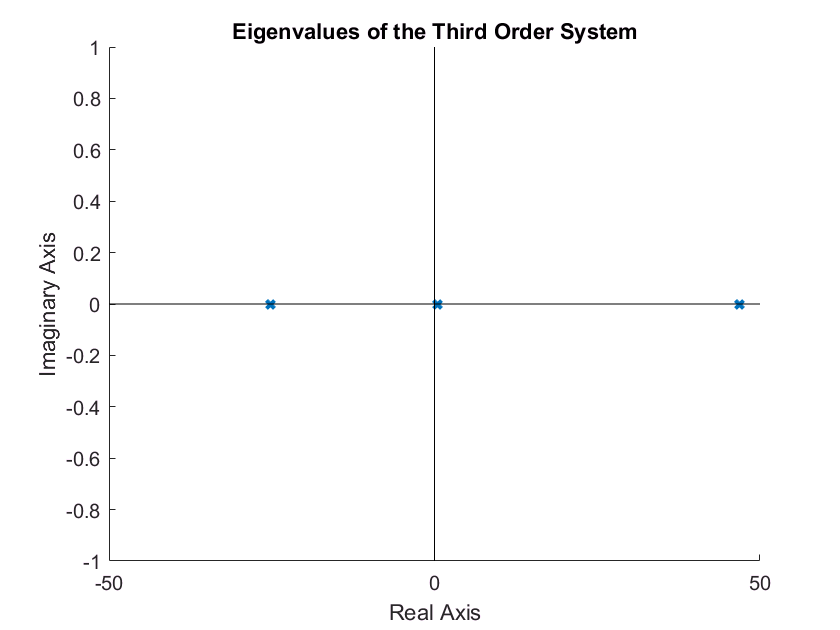

scatter(real(Aeig3),imag(Aeig3),'x','Linewidth',2)  %Plot the poles of the system
title('Eigenvalues of the Third Order System')
xlabel('Real Axis')
ylabel('Imaginary Axis')
line ([0 0], [-1 1],'Color',[0 0 0])
line( [-50 50], [0 0],'Color',[0 0 0])

Because this matrix has eigenvalues whose real components are positive, this system will be unstable.